#  Kinematic Analysis

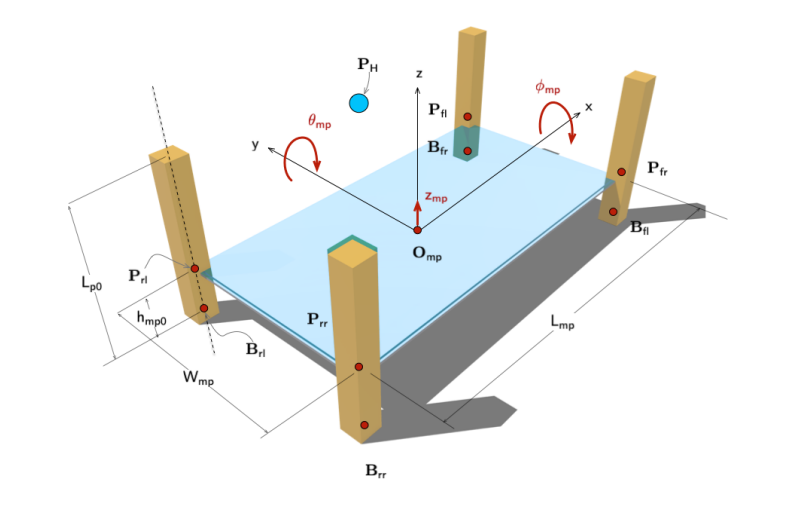

The kinematic and dynamic analysis of the multibody system was performed using the following  linear graph and a global approach.

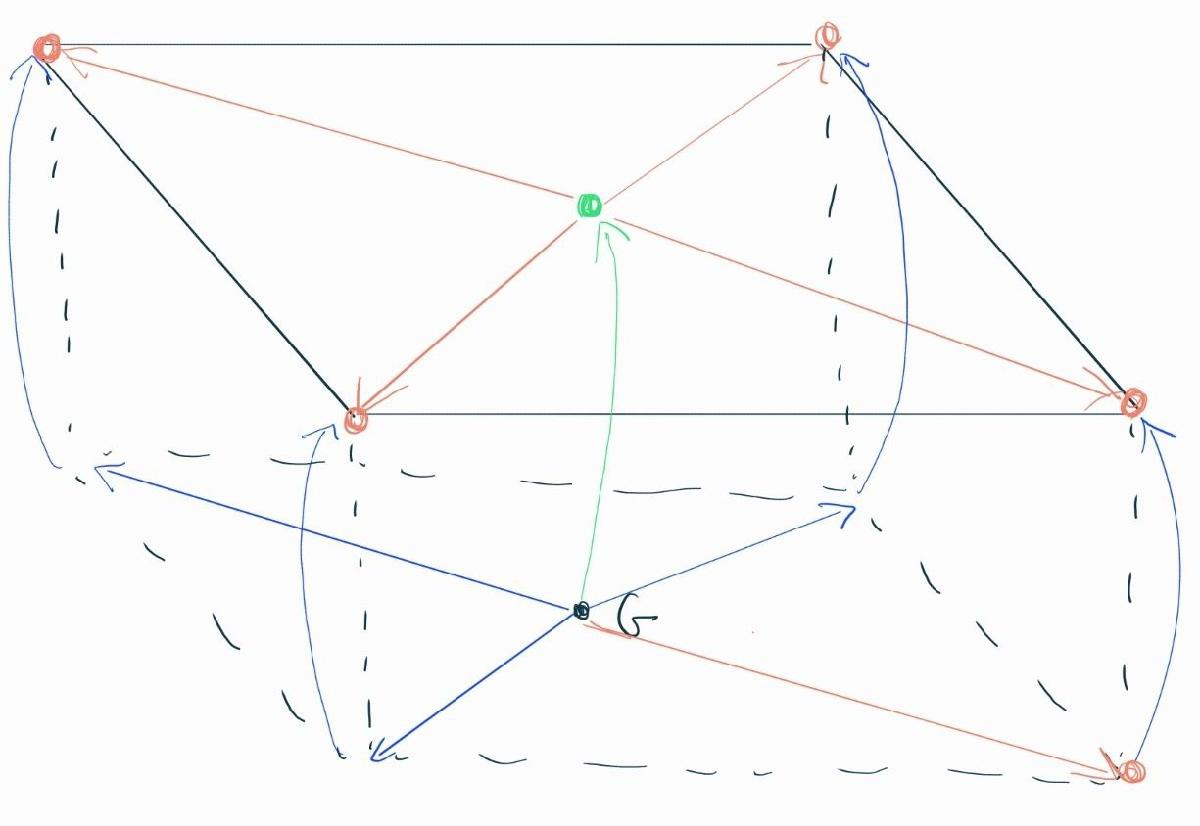

To solve the kinematic problem, one of the platform's feet is considered fixed, while the other three are treated as joints free to move in the x-y plane.

clear
clc
Lmp = 1.6;
Wmp = 0.82;
addpath('MBsLib_v2_1/')

TG=ground();
P0 = get_origin(TG);
x_rr = -Lmp/2;
y_rr = -Wmp/2;
syms x_fr y_fr x_fl y_fl x_rl y_rl

TBrr = translate([x_rr y_rr 0]);
TBfr = translate([x_fr y_fr 0]);
TBfl = translate([x_fl y_fl 0 ]);
TBrl = translate([x_rl y_rl 0]);

disp('fixed foot translation matrix:');

fixed foot translation matrix:


disp(TBrr);

    1.0000         0         0   -0.8000
         0    1.0000         0   -0.4100
         0         0    1.0000         0
         0         0         0    1.0000



disp('Translation Matrix for a Moving Foot:');

Translation Matrix for a Moving Foot:


disp(TBrl);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & x_{\mathrm{rl}}\\ 0 & 1 & 0 & y_{\mathrm{rl}}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Brr= project(subtract(P0, get_origin(TBrr)), TG).coords;
Brl= project(subtract(P0, get_origin(TBrl)), TG).coords;
Bfr= project(subtract(P0, get_origin(TBfr)), TG).coords;
Bfl= project(subtract(P0, get_origin(TBfl)), TG).coords;

A roto-translation matrix is defined to describe the transformation from the ground to the center of mass of the platform, where rotations occur only around the x and y axes.

syms x_mp y_mp z_mp phi_mp theta_mp
Tmp = translate([x_mp y_mp z_mp]) * rotate('X',phi_mp) * rotate('Y', theta_mp);
disp(Tmp)

$$\left(\begin{array}{cccc} \cos\left(\theta_{\mathrm{mp}}\right) & 0 & \sin\left(\theta_{\mathrm{mp}}\right) & x_{\mathrm{mp}}\\ \sin\left(\varphi_{\mathrm{mp}}\right)\,\sin\left(\theta_{\mathrm{mp}}\right) & \cos\left(\varphi_{\mathrm{mp}}\right) & -\cos\left(\theta_{\mathrm{mp}}\right)\,\sin\left(\varphi_{\mathrm{mp}}\right) & y_{\mathrm{mp}}\\ -\cos\left(\varphi_{\mathrm{mp}}\right)\,\sin\left(\theta_{\mathrm{mp}}\right) & \sin\left(\varphi_{\mathrm{mp}}\right) & \cos\left(\varphi_{\mathrm{mp}}\right)\,\cos\left(\theta_{\mathrm{mp}}\right) & z_{\mathrm{mp}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% i define the matrix with only rotations. Needed to define the rigid arm vectors on the top of the platform
Tmp_rotation =rotate('X',phi_mp) * rotate('Y', theta_mp);

Under the assumption of  small angles, this matrix can be simplified.

Tmp=subs(Tmp,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
Tmp_rotation=subs(Tmp_rotation,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
disp(Tmp);

$$\left(\begin{array}{cccc} 1 & 0 & \theta_{\mathrm{mp}} & x_{\mathrm{mp}}\\ \varphi_{\mathrm{mp}}\,\theta_{\mathrm{mp}} & 1 & -\varphi_{\mathrm{mp}} & y_{\mathrm{mp}}\\ -\theta_{\mathrm{mp}} & \varphi_{\mathrm{mp}} & 1 & z_{\mathrm{mp}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Fixed transformation matrices are also defined from the platform's center of mass to its edges in local coordinates.

TPrl = translate([-Lmp/2 Wmp/2 0]);
TPrr = translate([-Lmp/2 -Wmp/2 0]);
TPfl = translate([Lmp/2 Wmp/2 0]);
TPfr = translate([Lmp/2 -Wmp/2 0]);


Prl = Tmp_rotation*TPrl;
Prr = Tmp_rotation*TPrr;
Pfl = Tmp_rotation*TPfl;
Pfr = Tmp_rotation*TPfr;


Pcm= project(subtract(P0, get_origin(Tmp)), TG).coords;
Prl= project(subtract(P0, get_origin(Prl)), TG).coords;
Prr= project(subtract(P0, get_origin(Prr)), TG).coords;
Pfl= project(subtract(P0, get_origin(Pfl)), TG).coords;
Pfr= project(subtract(P0, get_origin(Pfr)), TG).coords;


The transformations from the base to the top of the actuator are modeled as a prismatic joint, which move vertically on an axis that shares the same rotation as the platform.

syms hmp_rr hmp_rl hmp_fl hmp_fr
THp_rr =  rotate('X',phi_mp) * rotate('Y', theta_mp) *translate([0 0 hmp_rr]);
THp_rl =  rotate('X',phi_mp) * rotate('Y', theta_mp)*translate([0 0 hmp_rl]);
THp_fl =  rotate('X',phi_mp) * rotate('Y', theta_mp)*translate([0 0 hmp_fl]);
THp_fr =  rotate('X',phi_mp) * rotate('Y', theta_mp)*translate([0 0 hmp_fr]);

disp(THp_fr);

$$\left(\begin{array}{cccc} \cos\left(\theta_{\mathrm{mp}}\right) & 0 & \sin\left(\theta_{\mathrm{mp}}\right) & {\mathrm{hmp}}_{\mathrm{fr}}\,\sin\left(\theta_{\mathrm{mp}}\right)\\ \sin\left(\varphi_{\mathrm{mp}}\right)\,\sin\left(\theta_{\mathrm{mp}}\right) & \cos\left(\varphi_{\mathrm{mp}}\right) & -\cos\left(\theta_{\mathrm{mp}}\right)\,\sin\left(\varphi_{\mathrm{mp}}\right) & -{\mathrm{hmp}}_{\mathrm{fr}}\,\cos\left(\theta_{\mathrm{mp}}\right)\,\sin\left(\varphi_{\mathrm{mp}}\right)\\ -\cos\left(\varphi_{\mathrm{mp}}\right)\,\sin\left(\theta_{\mathrm{mp}}\right) & \sin\left(\varphi_{\mathrm{mp}}\right) & \cos\left(\varphi_{\mathrm{mp}}\right)\,\cos\left(\theta_{\mathrm{mp}}\right) & {\mathrm{hmp}}_{\mathrm{fr}}\,\cos\left(\varphi_{\mathrm{mp}}\right)\,\cos\left(\theta_{\mathrm{mp}}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

These matrices are then simplified, again under the assumption of small angles.

THp_rr=subs(THp_rr,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
THp_rl=subs(THp_rl,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
THp_fl=subs(THp_fl,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
THp_fr=subs(THp_fr,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});

disp(THp_fr);

$$\left(\begin{array}{cccc} 1 & 0 & \theta_{\mathrm{mp}} & {\mathrm{hmp}}_{\mathrm{fr}}\,\theta_{\mathrm{mp}}\\ \varphi_{\mathrm{mp}}\,\theta_{\mathrm{mp}} & 1 & -\varphi_{\mathrm{mp}} & -{\mathrm{hmp}}_{\mathrm{fr}}\,\varphi_{\mathrm{mp}}\\ -\theta_{\mathrm{mp}} & \varphi_{\mathrm{mp}} & 1 & {\mathrm{hmp}}_{\mathrm{fr}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


Hp_rr= project(subtract(P0, get_origin(THp_rr)), TG).coords;
Hp_rl= project(subtract(P0, get_origin(THp_rl)), TG).coords;
Hp_fr= project(subtract(P0, get_origin(THp_fr)), TG).coords;
Hp_fl= project(subtract(P0, get_origin(THp_fl)), TG).coords;

**Direct kynematics**

Equations are created to find the coordinates for the feet, the platform, and a single actuator's length, all based on the lengths of the three other actuators. This is accomplished using the T-graph. It's worth noting that the R-graph equations do not need to be solved, as they are inherently satisfied because the joints undergo the same rotations as the plane itself.

eq_rr = Brr + Hp_rr -Prr - Pcm == 0;
eq_rl = Brl + Hp_rl -Prl - Pcm == 0;
eq_fl = Bfl + Hp_fl -Pfl - Pcm == 0;
eq_fr = Bfr + Hp_fr -Pfr - Pcm == 0;

eqs = [eq_rr(1:3);eq_fl(1:3);eq_fr(1:3);eq_rl(1:3)];
disp('T-graph equations:');

T-graph equations:


disp(eqs);

$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{hmp}}_{\mathrm{rr}}\,\theta_{\mathrm{mp}}-x_{\mathrm{mp}}=0\\ \sigma_{1}-{\mathrm{hmp}}_{\mathrm{rr}}\,\varphi_{\mathrm{mp}}-y_{\mathrm{mp}}=0\\ {\mathrm{hmp}}_{\mathrm{rr}}+\frac{41\,\varphi_{\mathrm{mp}}}{100}-\frac{4\,\theta_{\mathrm{mp}}}{5}-z_{\mathrm{mp}}=0\\ x_{\mathrm{fl}}-x_{\mathrm{mp}}+{\mathrm{hmp}}_{\mathrm{fl}}\,\theta_{\mathrm{mp}}-\frac{4}{5}=0\\ y_{\mathrm{fl}}-y_{\mathrm{mp}}-{\mathrm{hmp}}_{\mathrm{fl}}\,\varphi_{\mathrm{mp}}-\sigma_{1}-\frac{41}{100}=0\\ {\mathrm{hmp}}_{\mathrm{fl}}-\frac{41\,\varphi_{\mathrm{mp}}}{100}+\frac{4\,\theta_{\mathrm{mp}}}{5}-z_{\mathrm{mp}}=0\\ x_{\mathrm{fr}}-x_{\mathrm{mp}}+{\mathrm{hmp}}_{\mathrm{fr}}\,\theta_{\mathrm{mp}}-\frac{4}{5}=0\\ y_{\mathrm{fr}}-y_{\mathrm{mp}}-{\mathrm{hmp}}_{\mathrm{fr}}\,\varphi_{\mathrm{mp}}-\sigma_{1}+\frac{41}{100}=0\\ {\mathrm{hmp}}_{\mathrm{fr}}+\frac{41\,\varphi_{\mathrm{mp}}}{100}+\frac{4\,\theta_{\mathrm{mp}}}{5}-z_{\mathrm{mp}}=0\\ x_{\mathrm{rl}}-x_{\mathrm{mp}}+{\mathrm{hmp}}_{\mathrm{rl}}\,\theta_{\mathrm{mp}}+\frac{4}{5}=0\\ y_{\mathrm{rl}}-y_{\mathrm{mp}}-{\mathrm{hmp}}_{\mathrm{rl}}\,\varphi_{\mathrm{mp}}+\sigma_{1}-\frac{41}{100}=0\\ {\mathrm{hmp}}_{\mathrm{rl}}-\frac{41\,\varphi_{\mathrm{mp}}}{100}-\frac{4\,\theta_{\mathrm{mp}}}{5}-z_{\mathrm{mp}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4\,\varphi_{\mathrm{mp}}\,\theta_{\mathrm{mp}}}{5} \end{array}$$

sol_sym = solve(eqs, [hmp_rr x_mp y_mp z_mp phi_mp theta_mp x_fr y_fr x_fl y_fl x_rl y_rl]);
disp('Direct kynematics solution:')

Direct kynematics solution:


disp(sol_sym);

      hmp_rr: hmp_fr - hmp_fl + hmp_rl
        x_mp: (5*hmp_fl^2)/8 - (5*hmp_fl*hmp_rl)/4 - (5*hmp_fr*hmp_fl)/8 + (5*hmp_rl^2)/8 + (5*hmp_fr*hmp_rl)/8
        y_mp: (25*hmp_fl^2)/41 - (75*hmp_fl*hmp_fr)/41 - (25*hmp_rl*hmp_fl)/41 + (50*hmp_fr^2)/41 + (25*hmp_rl*hmp_fr)/41
        z_mp: hmp_fr/2 + hmp_rl/2
      phi_mp: (50*hmp_fl)/41 - (50*hmp_fr)/41
    theta_mp: (5*hmp_rl)/8 - (5*hmp_fl)/8
        x_fr: (5*hmp_fl^2)/8 - (5*hmp_fl*hmp_rl)/4 + (5*hmp_rl^2)/8 + 4/5
        y_fr: -41/100
        x_fl: (5*hmp_fl^2)/4 - (15*hmp_fl*hmp_rl)/8 - (5*hmp_fr*hmp_fl)/8 + (5*hmp_rl^2)/8 + (5*hmp_fr*hmp_rl)/8 + 4/5
        y_fl: (50*hmp_fl^2)/41 - (100*hmp_fl*hmp_fr)/41 + (50*hmp_fr^2)/41 + 41/100
        x_rl: (5*hmp_fr*hmp_rl)/8 - (5*hmp_fl*hmp_rl)/8 - (5*hmp_fl*hmp_fr)/8 + (5*hmp_fl^2)/8 - 4/5
        y_rl: (50*hmp_fl^2)/41 - (100*hmp_fl*hmp_fr)/41 + (50*hmp_fr^2)/41 + 41/100



z_sol= sol_sym.z_mp;
phi_sol= sol_sym.phi_mp;
thetha_sol = sol_sym.theta_mp;
h_sol=sol_sym.hmp_rr;

Next, the results are plotted for three specified actuator heights:

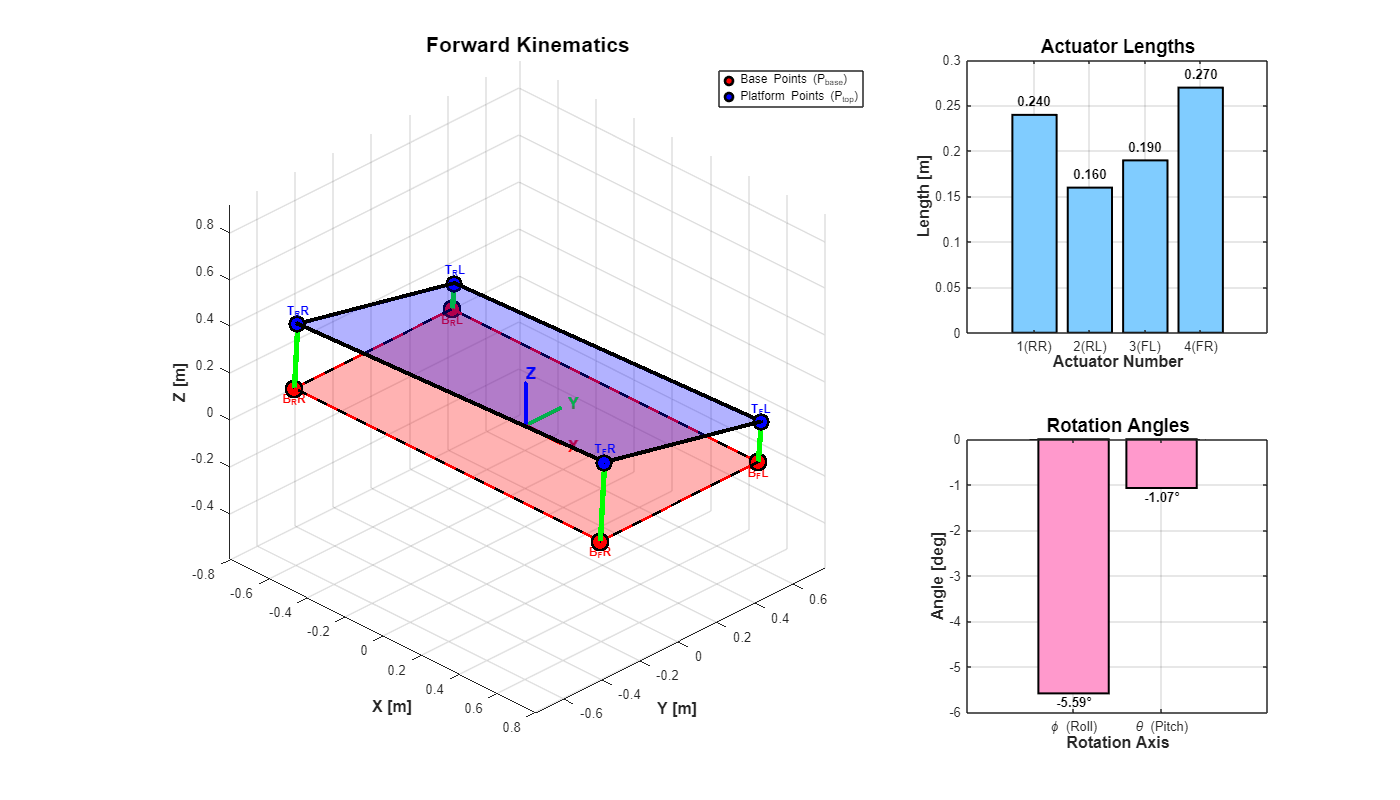

hrr = 0.1896+0.05;
hrl = 0.1896-0.03;
hfl = 0.1896;
eqs_sub = subs(eqs, [hmp_rr hmp_rl hmp_fl], [hrr hrl hfl]);
sol = solve(eqs_sub, [hmp_fr x_mp y_mp z_mp phi_mp theta_mp x_fr y_fr x_fl y_fl x_rl y_rl]);
P_top = zeros(4,3);

THp_rr_sub = subs(THp_rr, {theta_mp, phi_mp, hmp_rr}, {sol.theta_mp, sol.phi_mp, hrr});

tmp = THp_rr_sub * [double(x_rr); double(y_rr); 0; 1];
P_top(1, :) = tmp(1:3)';

THp_rl_sub = subs(THp_rl, {theta_mp, phi_mp, hmp_rl}, {sol.theta_mp, sol.phi_mp, hrl});

tmp = THp_rl_sub * [double(sol.x_rl); double(sol.y_rl); 0; 1];
P_top(2, :) = tmp(1:3)';

THp_fl_sub = subs(THp_fl, {theta_mp, phi_mp, hmp_fl}, {sol.theta_mp, sol.phi_mp, hfl});

tmp = THp_fl_sub * [double(sol.x_fl); double(sol.y_fl); 0; 1];
P_top(3, :) = tmp(1:3)';

THp_fr_sub = subs(THp_fr, {theta_mp, phi_mp, hmp_fr}, {sol.theta_mp, sol.phi_mp, double(sol.hmp_fr)});

tmp = THp_fr_sub * [double(sol.x_fr); double(sol.y_fr); 0; 1];
P_top(4, :) = tmp(1:3)';

P_base = zeros(4,3);

P_base(1, :) = [x_rr, y_rr, 0];

P_base(2, :) = [double(sol.x_rl), double(sol.y_rl), 0];

P_base(3, :) = [double(sol.x_fl), double(sol.y_fl), 0];

P_base(4, :) = [double(sol.x_fr), double(sol.y_fr), 0];
plot_stewart_fk(P_base, P_top, hrr, hrl, hfl, double(sol.hmp_fr), ...
                double(sol.phi_mp), double(sol.theta_mp))

**Inverse kynematics**

The inverse kinematics can be derived from the same set of equations obtained from the T-Graph. This allows the required actuator lengths to be computed for a given platform pose (position and orientation).

sol_inv = solve(eqs, [hmp_fr hmp_rr hmp_rl hmp_fl x_mp y_mp  x_fr y_fr x_fl y_fl x_rl y_rl]);
disp(sol_inv);

    hmp_fr: z_mp - (4*theta_mp)/5 - (41*phi_mp)/100
    hmp_rr: (4*theta_mp)/5 - (41*phi_mp)/100 + z_mp
    hmp_rl: (41*phi_mp)/100 + (4*theta_mp)/5 + z_mp
    hmp_fl: (41*phi_mp)/100 - (4*theta_mp)/5 + z_mp
      x_mp: (theta_mp*(80*theta_mp - 41*phi_mp + 100*z_mp))/100
      y_mp: (41*phi_mp^2)/100 - z_mp*phi_mp
      x_fr: (8*theta_mp^2)/5 + 4/5
      y_fr: -41/100
      x_fl: (8*theta_mp^2)/5 - (41*phi_mp*theta_mp)/50 + 4/5
      y_fl: (41*phi_mp^2)/50 + 41/100
      x_rl: - (41*phi_mp*theta_mp)/50 - 4/5
      y_rl: (41*phi_mp^2)/50 + 41/100



To verify the self-consistency of the models, the z, phi, and theta values obtained from the direct dynamics simulation were used as inputs for the inverse dynamics model. This test confirmed that the resulting system configuration is identical to the original one, thus validating the approach

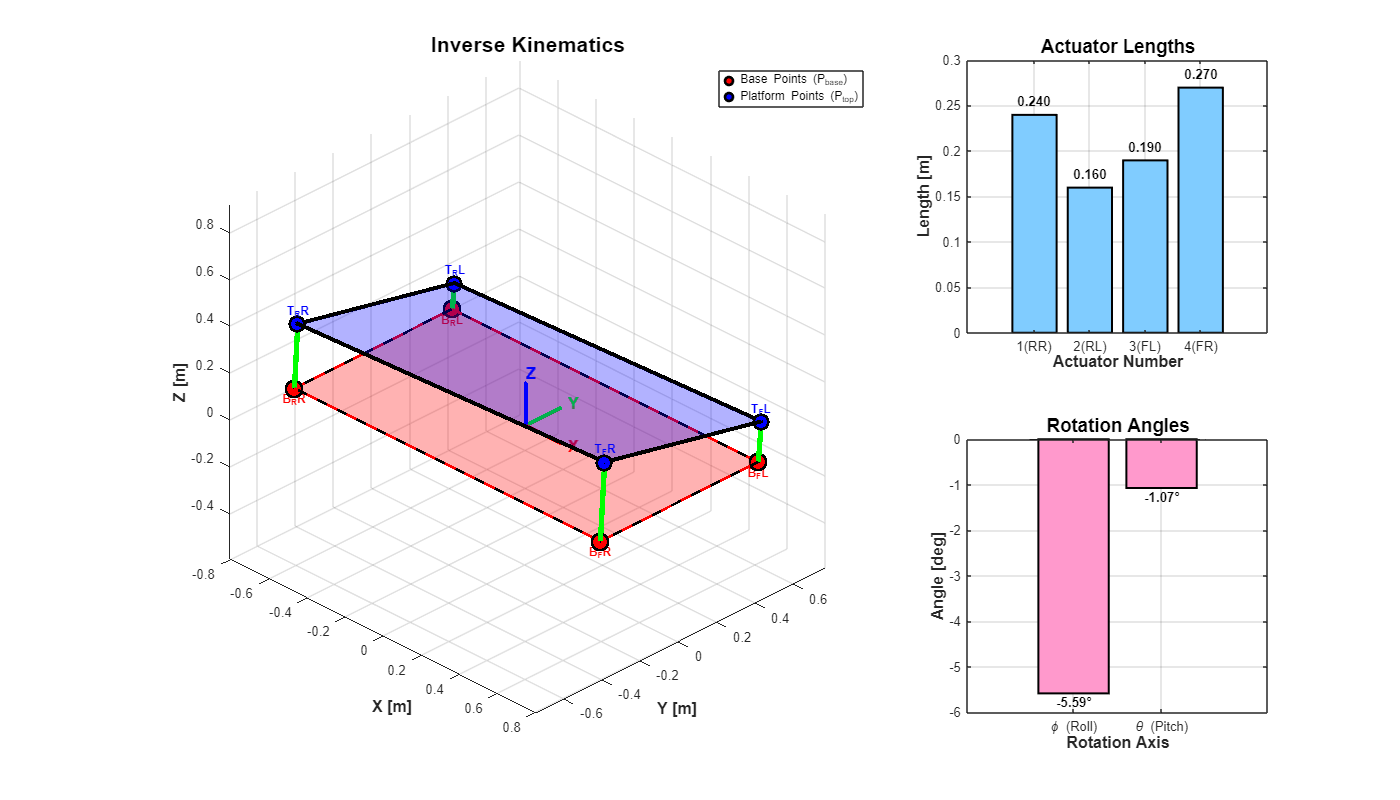

phi=sol.phi_mp;
theta=sol.theta_mp;
z=sol.z_mp;
eqs_inv_sub = subs(eqs, [z_mp phi_mp theta_mp], [z phi theta]);
sol = solve(eqs_inv_sub, [hmp_fr hmp_rr hmp_rl hmp_fl x_mp y_mp  x_fr y_fr x_fl y_fl x_rl y_rl]);

P_top = zeros(4,3);

THp_rr_sub = subs(THp_rr, {theta_mp, phi_mp, hmp_rr}, {theta, phi, double(sol.hmp_rr)});

tmp = THp_rr_sub * [double(x_rr); double(y_rr); 0; 1];
P_top(1, :) = tmp(1:3)';

THp_rl_sub = subs(THp_rl, {theta_mp, phi_mp, hmp_rl}, {theta, phi, double(sol.hmp_rl)});

tmp = THp_rl_sub * [double(sol.x_rl); double(sol.y_rl); 0; 1];
P_top(2, :) = tmp(1:3)';

THp_fl_sub = subs(THp_fl, {theta_mp, phi_mp, hmp_fl}, {theta, phi, double(sol.hmp_fl)});

tmp = THp_fl_sub * [double(sol.x_fl); double(sol.y_fl); 0; 1];
P_top(3, :) = tmp(1:3)';

THp_fr_sub = subs(THp_fr, {theta_mp, phi_mp, hmp_fr}, {theta, phi, double(sol.hmp_fr)});

tmp = THp_fr_sub * [double(sol.x_fr); double(sol.y_fr); 0; 1];
P_top(4, :) = tmp(1:3)';

P_base = zeros(4,3);

P_base(1, :) = [x_rr, y_rr, 0];

P_base(2, :) = [double(sol.x_rl), double(sol.y_rl), 0];

P_base(3, :) = [double(sol.x_fl), double(sol.y_fl), 0];

P_base(4, :) = [double(sol.x_fr), double(sol.y_fr), 0];
plot_stewart_inv(P_base, P_top, double(sol.hmp_rr), double(sol.hmp_rl), double(sol.hmp_fl), double(sol.hmp_fr), ...
                phi, theta)

**Motion ranges**

The system's workspace is evaluated based on the assumption that each actuator can travel ±50% of its full stroke from a central position.

The motion ranges are determined by evaluating the system's behavior at maximum and minimum actuator lengths. For small angles, the equations for each actuator's length are linear and independent. Therefore, the principle of superposition is applied: the system's total displacement is calculated as the sum of individual behaviors. This is done by varying one degree of freedom at a time while keeping the other two constant to isolate their effects.

h__mp0 = 0.1896;
stroke = 0.1;
Lmax=h__mp0+stroke/2; 
Lmin=h__mp0-stroke/2; 

z_max_var= double(subs(z_sol, [ hmp_rr hmp_rl hmp_fl hmp_fr], [Lmax Lmax Lmax Lmax]))   - h__mp0;
z_min_var= double(subs(z_sol, [ hmp_rr hmp_rl hmp_fl hmp_fr], [Lmin Lmin Lmin Lmin]))   - h__mp0;


eqs_sub= subs(eqs, [ hmp_rr hmp_rl hmp_fl  hmp_fr phi_mp], [Lmax Lmax Lmin Lmin 0]);
sol = solve(eqs_sub, [x_mp y_mp z_mp theta_mp x_fr y_fr x_fl y_fl x_rl y_rl]);
theta_var = double(sol.theta_mp*180/pi);

eqs_sub= subs(eqs, [ hmp_rr hmp_rl hmp_fl  hmp_fr theta_mp], [Lmax Lmin Lmin Lmax 0]);
sol = solve(eqs_sub, [x_mp y_mp z_mp phi_mp x_fr y_fr x_fl y_fl x_rl y_rl]);
phi_var = double(sol.phi_mp*180/pi);

The resulting theoretical motion ranges are summarized as follows:

- z (heave): ±50 mm

- θ (pitch): ±3.581 degrees

- φ (roll): ±6.9873 degrees

This confirms that the small-angle assumptions are valid. The following ranges represent the maximum and minimum for each degree of freedom when the others are inactive. Naturally, if other degrees of freedom have non-zero values, the available range for any given degree of freedom will be more restricted.

A discrepancy was noted between the calculated ranges for pitch and roll and those specified in the datasheet. This difference is resolved by repeating the calculation using the plate dimensions from the datasheet, which are slightly smaller than those provided in the assignment. Using the datasheet dimensions yields results that perfectly match the specified ranges for both angles.

**Pilot**

To compute the velocity and acceleration perceived by the driver, a point is defined to represent the position of their head. The driver is modeled as a rigid body (xp,yp,zp), whose movement is not autonomous but rather an indirect effect of the motion of the plate on which it rests. The resulting velocity and acceleration are then calculated at that specific point within the body-fixed frame.

syms xp yp zp
syms phi_mp(t) theta_mp(t) x_mp(t) y_mp(t) z_mp(t)

g = 9.81; 
Tmp_t = subs(Tmp,{ phi_mp theta_mp x_mp y_mp z_mp},{phi_mp(t) theta_mp(t) x_mp(t) y_mp(t) z_mp(t)});
Tpilot = Tmp_t* translate([xp yp zp]);
rbp = project(subtract(P0,get_origin(Tpilot)), TG);
disp('pilot position:')

pilot position:


disp(rbp.coords(1:3));

$$\left(\begin{array}{c} \mathrm{xp}+x_{\mathrm{mp}}\left(t\right)+\mathrm{zp}\,\theta_{\mathrm{mp}}\left(t\right)\\ \mathrm{yp}+y_{\mathrm{mp}}\left(t\right)-\mathrm{zp}\,\varphi_{\mathrm{mp}}\left(t\right)+\mathrm{xp}\,\varphi_{\mathrm{mp}}\left(t\right)\,\theta_{\mathrm{mp}}\left(t\right)\\ \mathrm{zp}+z_{\mathrm{mp}}\left(t\right)+\mathrm{yp}\,\varphi_{\mathrm{mp}}\left(t\right)-\mathrm{xp}\,\theta_{\mathrm{mp}}\left(t\right) \end{array}\right)$$

VG = velocity(rbp);
disp('pilot linear velocity');

pilot linear velocity


disp(VG.coords(1:3));

$$\left(\begin{array}{c} \mathrm{zp}\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)+\frac{\partial }{\partial t}x_{\mathrm{mp}}\left(t\right)\\ \frac{\partial }{\partial t}y_{\mathrm{mp}}\left(t\right)-\mathrm{zp}\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)+\mathrm{xp}\,\varphi_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)+\mathrm{xp}\,\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ \mathrm{yp}\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)-\mathrm{xp}\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)+\frac{\partial }{\partial t}z_{\mathrm{mp}}\left(t\right) \end{array}\right)$$

AG = add(velocity(VG),make_VECTOR(TG,[0 0 -g]));
disp('pilot linear accelleration');

pilot linear accelleration


disp(AG.coords(1:3));

$$\begin{array}{l} \left(\begin{array}{c} \mathrm{zp}\,\sigma_{1}+\frac{\partial^{2}}{\partial t^{2}}x_{\mathrm{mp}}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y_{\mathrm{mp}}\left(t\right)-\mathrm{zp}\,\sigma_{2}+2\,\mathrm{xp}\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)+\mathrm{xp}\,\varphi_{\mathrm{mp}}\left(t\right)\,\sigma_{1}+\mathrm{xp}\,\theta_{\mathrm{mp}}\left(t\right)\,\sigma_{2}\\ \mathrm{yp}\,\sigma_{2}-\mathrm{xp}\,\sigma_{1}+\frac{\partial^{2}}{\partial t^{2}}z_{\mathrm{mp}}\left(t\right)-\frac{981}{100} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{\mathrm{mp}}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\varphi_{\mathrm{mp}}\left(t\right) \end{array}$$


[SOmega_p,omega_p] = angular_velocity(Tpilot);
disp('pilot angular velocity');

pilot angular velocity


disp(omega_p.coords(1:3));

$$\left(\begin{array}{c} \frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)-\varphi_{\mathrm{mp}}\left(t\right)\,\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ \theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right) \end{array}\right)$$


alpha_p= velocity(omega_p);
disp('pilot angular accelleration')

pilot angular accelleration


disp(simplify(alpha_p.coords(1:3)));

$$\begin{array}{l} \left(\begin{array}{c} \left({\theta_{\mathrm{mp}}\left(t\right)}^{2}+1\right)\,\sigma_{1}+2\,\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ \sigma_{3}-\theta_{\mathrm{mp}}\left(t\right)\,\sigma_{2}-\varphi_{\mathrm{mp}}\left(t\right)\,\theta_{\mathrm{mp}}\left(t\right)\,\sigma_{1}-\varphi_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ -\theta_{\mathrm{mp}}\left(t\right)\,{\varphi_{\mathrm{mp}}\left(t\right)}^{2}\,\sigma_{1}+\varphi_{\mathrm{mp}}\left(t\right)\,\sigma_{3}-2\,\theta_{\mathrm{mp}}\left(t\right)\,\varphi_{\mathrm{mp}}\left(t\right)\,\sigma_{2}-\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,{\varphi_{\mathrm{mp}}\left(t\right)}^{2}\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)+\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\varphi_{\mathrm{mp}}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta_{\mathrm{mp}}\left(t\right) \end{array}$$

# Dynamic Modeling

To ensure efficient computation time for the dynamic analysis, a reduction in the number of coordinates and constraints is necessary. The methodology is as follows:

- Selection of Coordinates: A set of generalized coordinates, q, is chosen to include the platform's vertical position (z_mp), its pitch (theta_mp) and roll (phi_mp) angles, and the four actuator heights (hmp).

- Imposing Constraints: The relevant constraint for thegeneralized coordinates are selected from the `T-graph equations`. The motion of three actuators is defined as a prescribed function of time. This allows their lengths to be treated as direct inputs for the system analysis.

- Resulting System: By defining the motion of three actuators, the platform's three degrees of freedom are effectively constrained, reducing the system's final degrees of freedom to zero.

syms f_1(t) f_2(t) f_3(t) 
eqs_subset = [eqs(3);eqs(6);eqs(9);eqs(12);hmp_fr-f_1(t)== 0; hmp_rl-f_2(t)== 0;hmp_fl-f_3(t)== 0];

syms hmp_rr(t) hmp_rl(t) hmp_fl(t) hmp_fr(t)  t

q= [z_mp(t) phi_mp(t) theta_mp(t) hmp_rr(t) hmp_rl(t) hmp_fl(t) hmp_fr(t)];
eqs_t=subs(eqs_subset,{z_mp phi_mp theta_mp  hmp_rr hmp_rl hmp_fl hmp_fr},q);
disp('Constraints equations:');

Constraints equations:


disp(eqs_t);

$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{hmp}}_{\mathrm{rr}}\left(t\right)+\sigma_{2}-\sigma_{1}-z_{\mathrm{mp}}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{fl}}\left(t\right)-\sigma_{2}+\sigma_{1}-z_{\mathrm{mp}}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{fr}}\left(t\right)+\sigma_{2}+\sigma_{1}-z_{\mathrm{mp}}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{rl}}\left(t\right)-\sigma_{2}-\sigma_{1}-z_{\mathrm{mp}}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{fr}}\left(t\right)-f_{1}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{rl}}\left(t\right)-f_{2}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{fl}}\left(t\right)-f_{3}\left(t\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4\,\theta_{\mathrm{mp}}\left(t\right)}{5}\\ \sigma_{2}=\frac{41\,\varphi_{\mathrm{mp}}\left(t\right)}{100} \end{array}$$

G_q = sym(zeros(size(eqs_t))); % Pre-allocate a symbolic array for the left-hand sides
for i = 1:numel(eqs_t)
    G_q(i) = lhs(eqs_t(i));
end


% 4. Compute the Jacobian dG/dq
J_constraint = jacobian(G_q, q);

% disp('Jacobian (dG/dq):');
% disp(J_constraint)

R = rank(J_constraint);
disp(['Rank of Jacobian: ', num2str(R)]);

Rank of Jacobian: 7



num_constraints = size(G_q, 1);
num_generalized_coords = size(q.',1);

disp(['Number of constraints (M): ', num2str(num_constraints)]);

Number of constraints (M): 7


disp(['Number of generalized coordinates (N): ', num2str(num_generalized_coords)]);

Number of generalized coordinates (N): 7




if R < num_constraints
    disp('Warning: The constraints are linearly dependent (redundant) or the system is in a singular configuration.');
    disp(['Actual independent constraints: ', num2str(R)]);
else
    disp('The constraints are linearly independent in this configuration.');
end

The constraints are linearly independent in this configuration.



disp(['Number of DOF: ', num2str(num_generalized_coords- num_constraints)]);

Number of DOF: 0


As expected, using three additional constraints to control the actuator positions as a function of time has reduced the system's degrees of freedom (DOF) to zero. Otherwise, if the actuators had been controlled by force instead of by adding a constraint, the system would have had three degrees of freedom. 

Subsequently, the potential and kinetic energy are expressed as a function of the generalized coordinates in order to use the energy in the Lagrangian formulation:

                                                                                                                                                                            
$$\frac{d}{\mathrm{dt}}\left(\frac{\mathrm{dL}}{{{\mathrm{dq}}_i }^{\prime } }\right)-\frac{\mathrm{dL}}{{\mathrm{dq}}_i }-\lambda \frac{d\Phi }{{\mathrm{dq}}_i }=Q_i$$


m_actuator = 30; % mass of actuator [kg]
m_platform = 150;
m_driver = 75;

%i need to express x_mp(t) y_mp(t) in function of my vector q, so i use the
%results of the kinematics
sol_new_xmp = subs(sol_sym.x_mp,{ phi_mp theta_mp z_mp},{phi_mp(t) theta_mp(t) z_mp(t)});
sol_new_ymp = subs(sol_sym.y_mp,{ phi_mp theta_mp z_mp},{phi_mp(t) theta_mp(t) z_mp(t)});


Tmp_t_new = subs(Tmp_t,[x_mp(t),y_mp(t)],[sol_new_xmp, sol_new_ymp]);

center = project(subtract(P0,get_origin(Tmp_t_new)), TG);
velocity_platform = velocity(center).coords(1:3);

% Tpilot = Tmp_t_new* translate([xp yp zp]);
% rbp = project(subtract(P0,get_origin(Tpilot)), TG);
% velocity_driver =velocity(rbp).coords(1:3);

% translational kinetic energy of actuators
T_rr = Tmp_t_new*TPrr;

rr = project(subtract(P0, get_origin(T_rr)), TG);

%for small angle i can consider the z of the actuator in the global system as the length of the actuator. I need to use this becouse the lagrangian should be function of all q. The x and y of the actuar remain function 
% only of the center of mas of the platform becouse otherway they are function of the position of their base( which is changing) and  this would introduce other variables
rr.coords(3) = hmp_rr(t);
V_rr = velocity(rr).coords(1:3);

T_trans_actuators(1) = (1/2) * (m_actuator) * (V_rr.' * V_rr);

T_fl = Tmp_t_new*TPfl;
fl = project(subtract(P0, get_origin(T_fl)), TG);
fl.coords(3) = hmp_fl(t);

V_fl = velocity(fl).coords(1:3);

T_trans_actuators(2) = (1/2) * (m_actuator) * (V_fl.' * V_fl);

T_fr = Tmp_t_new*TPfr;
fr = project(subtract(P0, get_origin(T_fr)), TG);
fr.coords(3) = hmp_fr(t);

V_fr = velocity(fr).coords(1:3);

T_trans_actuators(3) = (1/2) * (m_actuator) * (V_fr.' * V_fr);

% T_rl = TBrl_t * THp_rl_t;
T_rl = Tmp_t_new*TPrl;

rl = project(subtract(P0, get_origin(T_rl)), TG);
rl.coords(3) = hmp_rl(t);
V_rl = velocity(rl).coords(1:3);

T_trans_actuators(4) = (1/2) * (m_actuator) * (V_rl.' * V_rl);

% translational kinetic energy of platform
T_trans_platform = (1/2) * (m_platform) * (velocity_platform.' * velocity_platform);

% translational kinetic energy of driver
% T_trans_driver = (1/2) * m_driver * (velocity_driver.' * velocity_driver);

% total translational kinetic energy
T_trans_total = T_trans_platform ;%+ T_trans_driver;

for i = 1:4
    T_trans_total = T_trans_total + T_trans_actuators(i);
end

% dimensions of actuators [m]
height = 559.8 / 1000;
width = 92 / 1000;  %y
lenght = 106 / 1000; %x

% inertias of actuators [kg * m^2] % Ixy ???
Ix_actuator = (1/12) * m_actuator * (height^2 + width^2);
Iy_actuator = (1/12) * m_actuator * (height^2 + lenght^2);
Iz_actuator = (1/12) * m_actuator * (width^2 + lenght^2);

% height of platform [m]
height = 0.3;
width = Wmp;
lenght = Lmp;

% inertias of platform [kg * m^2]
Ix_platform1 = (1/12) * m_platform * (height^2 + width^2);
Iy_platform1 = (1/12) * m_platform * (height^2 + lenght^2);
Iz_platform = (1/12) * m_platform * (width^2 + lenght^2);

% distaces between actuators and platform [m]
d_x = Lmp / 2;
d_y = Wmp / 2;

% Huygens-Steiner theorem 
Ix_platform = Ix_actuator + Ix_platform1 + (m_actuator * d_x^2);
Iy_platform = Iy_actuator + Iy_platform1 + (m_actuator * d_y^2);

theta_dot = diff(theta_mp, t);
phi_dot = diff(phi_mp, t);

T_rot_platform = (1/2) * Ix_platform * phi_dot^2 + (1/2) * Iy_platform * theta_dot^2;

% T_rot_driver = (1/2) * Ix_driver * phi_dot^2 + (1/2) * Iy_driver * theta_dot^2

T_tot = T_trans_total + T_rot_platform;

disp('kinetic energy:')

kinetic energy:


disp(simplify(T_tot ));

$$15\,{\left(\frac{\partial }{\partial t}{\mathrm{hmp}}_{\mathrm{fl}}\left(t\right)\right)}^{2}+15\,{\left(\frac{\partial }{\partial t}{\mathrm{hmp}}_{\mathrm{fr}}\left(t\right)\right)}^{2}+15\,{\left(\frac{\partial }{\partial t}{\mathrm{hmp}}_{\mathrm{rl}}\left(t\right)\right)}^{2}+15\,{\left(\frac{\partial }{\partial t}{\mathrm{hmp}}_{\mathrm{rr}}\left(t\right)\right)}^{2}+\frac{4156625437653019\,{\left(\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\right)}^{2}}{281474976710656}+\frac{1371470290886227\,{\left(\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\right)}^{2}}{70368744177664}+75\,{\left(\frac{\partial }{\partial t}z_{\mathrm{mp}}\left(t\right)\right)}^{2}+\frac{192\,{\left(\varphi_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)+\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\right)}^{2}}{5}$$


% potential energy
V_platform = m_platform * g * z_mp(t);

V_actuators(1) = m_actuator * g * fl.coords(3);
V_actuators(2) = m_actuator * g * fr.coords(3);
V_actuators(3) = m_actuator * g * rr.coords(3);
V_actuators(4) = m_actuator * g * rl.coords(3);

V_driver = m_driver * g * rbp.coords(3);
V_driver=0; %%!!!!!

V_tot = V_platform + V_driver;

for i = 1:4
    V_tot = V_tot + V_actuators(i);
end

disp('potential energy:')

potential energy:


disp(simplify(V_tot ));

$$\frac{2943\,{\mathrm{hmp}}_{\mathrm{fl}}\left(t\right)}{10}+\frac{2943\,{\mathrm{hmp}}_{\mathrm{fr}}\left(t\right)}{10}+\frac{2943\,{\mathrm{hmp}}_{\mathrm{rl}}\left(t\right)}{10}+\frac{2943\,{\mathrm{hmp}}_{\mathrm{rr}}\left(t\right)}{10}+\frac{2943\,z_{\mathrm{mp}}\left(t\right)}{2}$$


L = T_tot - V_tot;

lambdas = sym('lambda', [num_constraints, 1]).';

q_dot = diff(q, t);

L_diff_q = jacobian(L, q);
L_diff_q_dot = jacobian(L, q_dot);

L_diff_q_dot_diff_t = diff(L_diff_q_dot, t);

dynamics = L_diff_q_dot_diff_t.' - L_diff_q.' + J_constraint.' * lambdas.' == 0;%Q_ext;

q_dot_dot= diff(q,t,2);
a_vars = sym('a', [num_generalized_coords, 1]).'; 
syms v1(t) v2(t) v3(t) v4(t) v5(t) v6(t) v7(t) v8(t) v9(t)
v_vars = [v1(t) v2(t) v3(t) v4(t) v5(t) v6(t) v7(t)];

dynamics =subs(dynamics, q_dot_dot, a_vars);
dynamics =subs(dynamics, q_dot, v_vars);

disp('Equations of Motion for the Generalized Variables:')

Equations of Motion for the Generalized Variables:


sol_d= solve(dynamics,a_vars)

sol_d = struct with fields:
    a1: lambda1/150 + lambda2/150 + lambda3/150 + lambda4/150 - 981/100
    a2: -(35184372088832*(281151409631676535*lambda1 - 281151409631676535*lambda2 + 281151409631676535*lambda3 - 281151409631676535*lambda4 + 553942754166571008*lambda1*phi_mp(t)^2 - 553942754166571008*lambda2*phi_mp(t)^2 + 553942754166571008*lambda3*…
    a3: -(140737488355328*(103915635941325475*lambda2 - 103915635941325475*lambda1 + 103915635941325475*lambda3 - 103915635941325475*lambda4 - 270215977642229760*lambda1*theta_mp(t)^2 + 270215977642229760*lambda2*theta_mp(t)^2 + 270215977642229760*lam…
    a4: - lambda1/30 - 981/100
    a5: - lambda4/30 - lambda6/30 - 981/100
    a6: - lambda2/30 - lambda7/30 - 981/100
    a7: - lambda3/30 - lambda5/30 - 981/100



% Ciclo per costruire e memorizzare le equazioni
for i = 1:7
    fieldName = ['a' num2str(i)];
    a_vars(i) = sol_d.(fieldName);
end

The resulting system is a set of Differential-Algebraic Equations (DAE), composed of both a differential part (the equations of motion) and an algebraic part (the constraint equations).

### Index Reduction and converting the model for numerical solution

To determine the index of the DAE, we compute the Jacobian of the constraint equations with respect to the Lagrange multipliers. If the Jacobian is not full-rank, the constraints cannot yet be solved for the multipliers, indicating an index greater than 1.

derivs_to_sub= [q_dot,diff(v_vars,t)];
expr_to_sub_with =[v_vars,a_vars];


J = jacobian(G_q, lambdas);
fprintf('max_rank: %d | Rank: %d | Determinant is non-zero: %s\n', ...
    size(J,1), rank(J), string(~isequal(det(J), sym(0))));

max_rank: 7 | Rank: 0 | Determinant is non-zero: false


As expected, the Jacobian is singular, confirming that the system is not of index-1. We proceed to differentiate the constraint equations once with respect to time, and substitute the known expressions for the derivatives.

#### First derivation

G_q_dt = diff(G_q, t);

G_q_dt_subs = simplify(subs(G_q_dt,derivs_to_sub,expr_to_sub_with));

J = jacobian(G_q_dt_subs, lambdas);
fprintf('max_rank: %d | Rank: %d | Determinant is non-zero: %s\n', ...
    size(J,1), rank(J), string(~isequal(det(J), sym(0))));

max_rank: 7 | Rank: 0 | Determinant is non-zero: false


**Second derivation**

G_q_dt2 = diff(G_q_dt_subs, t);

G_q_dt2_subs = simplify(subs(G_q_dt2,derivs_to_sub,expr_to_sub_with));

J = jacobian(G_q_dt2_subs, lambdas);
fprintf('max_rank: %d | Rank: %d | Determinant is non-zero: %s\n', ...
    size(J,1), rank(J), string(~isequal(det(J), sym(0))));

max_rank: 7 | Rank: 7 | Determinant is non-zero: true


This time, the Jacobian is full-rank and nonsingular. This confirms that the system has been reduced to index-1, and is now in a form suitable for numerical integration. The system is formally of index-3, as two differentiations were required.

Finally, we solve the second-derivative constraint system to obtain explicit expressions for the Lagrange multipliers.

eqns = G_q_dt2_subs==0;
S = solve(eqns,lambdas);
lambdas_sol = sym(zeros(0, num_constraints));
for i = 1:num_constraints
    fieldName = ['lambda' num2str(i)];
    lambdas_sol(i) = S.(fieldName);
end

disp('Equation of the lagrange multiplier');

Equation of the lagrange multiplier


disp(S);

    lambda1: 30*diff(f_3(t), t, t) - 30*diff(f_2(t), t, t) - 30*diff(f_1(t), t, t) - 2943/10
    lambda2: 30*phi_mp(t)^2*diff(f_3(t), t, t) - 30*phi_mp(t)^2*diff(f_2(t), t, t) - (192000*theta_mp(t)^2*diff(f_1(t), t, t))/1681 + (192000*theta_mp(t)^2*diff(f_3(t), t, t))/1681 - 96*phi_mp(t)*v2(t)*v3(t) + (7680*theta_mp(t)*v2(t)*v3(t))/41 - (4372…
    lambda3: (192000*theta_mp(t)^2*diff(f_1(t), t, t))/1681 - (192000*theta_mp(t)^2*diff(f_3(t), t, t))/1681 - (7680*theta_mp(t)*v2(t)*v3(t))/41 + (6590173638522681835*diff(f_1(t), t, t))/59144929481326592 + (135*diff(f_2(t), t, t))/2 - (4372238782972…
    lambda4: 30*phi_mp(t)^2*diff(f_2(t), t, t) - 30*phi_mp(t)^2*diff(f_3(t), t, t) + 96*phi_mp(t)*v2(t)*v3(t) + (135*diff(f_1(t), t, t))/2 + (186283244695909915*diff(f_2(t), t, t))/2251799813685248 - (101840751682713115*diff(f_3(t), t, t))/22517998136…
    lambda5: (192000*theta_mp(t)^2*diff(f_3(t), t, t))/1681 - (192000*theta_mp(t)^2*diff(f_1(t), t, t))/1681 + (7680*theta_mp(t)*v2(t)*v3(t))/41 - (

# System Response Analysis

Once the system has been reduced to index-1, we can numerically integrate it using a standard ODE solver. In this case, we use ode45. Before doing so, it is essential to ensure that the initial state satisfies both the position-level and velocity-level constraints, otherwise numerical errors will grow rapidly over time.

**Sinusoidal**

For the system analysis, three functions f_1, f_2, and f_3 are defined. These functions serve as the time-varying length inputs for the actuators.

h__mp0 = double(354.900/1000);
stroke= 0.025;
f_1_sub = h__mp0+stroke*sin(1*t); %  fr  top rigth
f_2_sub = h__mp0+0.001*sin(1.1*t); %  rl  base left
f_3_sub = h__mp0+0.03*sin(1*t); %  fl  top left
disp('f_1:');

f_1:


disp(f_1_sub);

$$\frac{\sin\left(t\right)}{40}+\frac{3549}{10000}$$

disp('f_2:');

f_2:


disp(f_2_sub);

$$\frac{\sin\left(\frac{11\,t}{10}\right)}{1000}+\frac{3549}{10000}$$

disp('f_3:');

f_3:


disp(f_3_sub);

$$\frac{3\,\sin\left(t\right)}{100}+\frac{3549}{10000}$$

The solution to the Ordinary Differential Equation (ODE) is initiated by defining the initial conditions, which are derived from the  constraints functions 

constraint = [G_q; G_q_dt_subs];
variables = [q,v_vars];

%needed to find intial velocities
syms v1 v2 v3 v4 v5 v6 v7
solution = solve(subs(G_q_dt_subs==0,v_vars,[v1 v2 v3 v4 v5 v6 v7] ),[v1 v2 v3 v4 v5 v6 v7]);
v_vars_sol = sym(zeros(0, num_generalized_coords));
for i = 1:num_generalized_coords
    fieldName = ['v' num2str(i)];
    v_vars_sol(i) = solution.(fieldName);
end

v_vars_sol_sin=subs(v_vars_sol, [f_1(t),f_2(t),f_3(t)], [f_1_sub,f_2_sub,f_3_sub]);
v_vars_sol_sin= @(t_num) double(subs(v_vars_sol_sin, t, t_num));

h1=h__mp0;
h2=h__mp0;
h3=h__mp0;
%needed to declare them again becouse now they are in function of t but not
%for the h_sol z_sol ...
syms hmp_fr hmp_rl hmp_fl
hrr=subs(h_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
z=subs(z_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
thetha=subs(thetha_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
phi=subs(phi_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);

initialState = [z, phi, thetha, h1, h2, h3, hrr, v_vars_sol_sin(0)];
disp('Initial state of the generalized coordinates and their first-order derivatives:');

Initial state of the generalized coordinates and their first-order derivatives:


disp(initialState);

$$\left(\begin{array}{cccccccccccccc} \frac{3549}{10000} & 0 & 0 & \frac{3549}{10000} & \frac{3549}{10000} & \frac{3549}{10000} & \frac{3549}{10000} & \frac{261}{20000} & \frac{1}{164} & -\frac{289}{16000} & -\frac{39}{10000} & \frac{11}{10000} & \frac{3}{100} & \frac{1}{40} \end{array}\right)$$

This check ensures that both the holonomic and hidden (velocity-level) constraints are satisfied at time zero. Failing to meet these would invalidate the results of any integration process.

#### integration

Next, the system of differential equations is defined. This is achieved by substituting the previously solved expressions for the Lagrange multipliers into the DAE, effectively converting the system into a set of Ordinary Differential Equations (ODEs).

velocity_eqns = a_vars.';
velocity_eqns_sub = simplify(subs(velocity_eqns,lambdas,lambdas_sol));
velocity_eqns_sub = simplify(subs(velocity_eqns_sub,[xp,yp,zp],[0.5,0.5,0.5]));


velocity_eqns_sub_sin = subs(velocity_eqns_sub,[f_1(t),f_2(t),f_3(t)],[f_1_sub,f_2_sub,f_3_sub]);
state_vars = [q,v_vars];
velocity_eqns_fun_sin = @(t_numerical,y) double(subs(velocity_eqns_sub_sin, [state_vars,t], [y(:).',t_numerical]));
daeFun = @(t, y) [
    y(8);   % dz/dt
    y(9);   % dphi/dt
    y(10);   % dthetha/dt
    y(11);   % dhrr/dt
    y(12);   % dhrl/dt
    y(13);   % dhfl/dt
    y(14);   % dhfr/dt
    velocity_eqns_fun_sin(t,y)
];

simParams.t_start = 0;   % Initial time
simParams.t_end = 10;    % Final time
simParams.h = 0.01;      % Fixed step size (critical for comparison)
simParams.tspan = simParams.t_start:simParams.h:simParams.t_end;

%state = ode4(daeFun,simParams.t_start, simParams.h , simParams.t_end, initialState);
[time,state] = ode45(daeFun, simParams.tspan, double(initialState));

The results obtained for the sinusoidal inputs are now presented below.

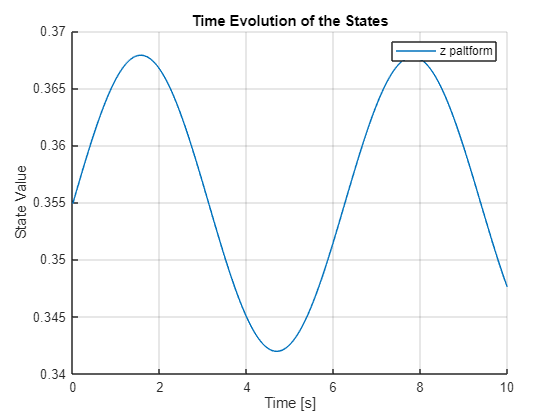

figure;
hold on;

numStates = min(1, size(state, 2));
for i = 1:numStates
    plot(simParams.tspan, state(:, i), 'DisplayName', ['z paltform']);
end

xlabel('Time [s]');
ylabel('State Value');
legend show;
title('Time Evolution of the States');
grid on;

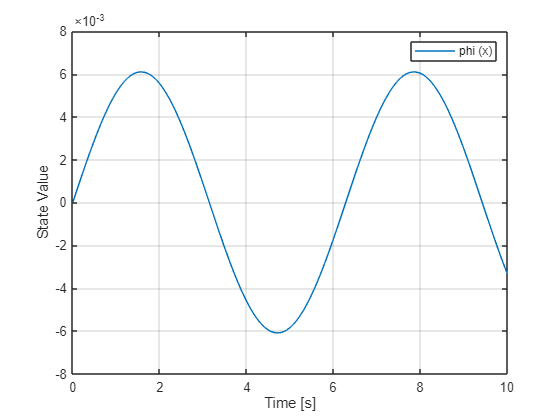


figure;

numStates = min(2, size(state, 2));  %phi
plot(simParams.tspan, state(:, numStates), 'DisplayName', ['phi (x)']);
xlabel('Time [s]');
ylabel('State Value');
legend show;
grid on;

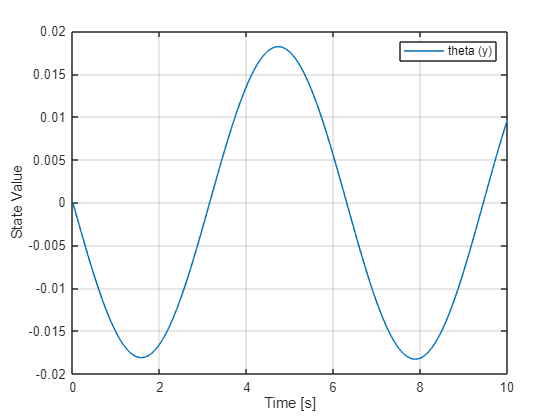


numStates = min(3, size(state, 2));  %phi
plot(simParams.tspan, state(:, numStates), 'DisplayName', ['theta (y) ']);
xlabel('Time [s]');
ylabel('State Value');
legend show;
grid on;

**Impulse**

For the system analysis, three functions f_1, f_2, and f_3 are defined. These functions serve as the time-varying length inputs for the actuators.

k = 5;       % Pendenza
t0 = 1;      % Centro della rampa

f_1_sub = 1 ./ (1 + exp(-k * (t - t0)));
f_2_sub = 1 ./ (1 + exp(-k * (t - t0)));
f_3_sub = 1 ./ (1 + exp(-k * (t - t0)));
disp('f_1:');

f_1:


disp(f_1_sub);

$$\frac{1}{{\mathrm{e}}^{5-5\,t}+1}$$

disp('f_2:');

f_2:


disp(f_2_sub);

$$\frac{1}{{\mathrm{e}}^{5-5\,t}+1}$$

disp('f_3:');

f_3:


disp(f_3_sub);

$$\frac{1}{{\mathrm{e}}^{5-5\,t}+1}$$


%------------------initial condition------------------------
v_vars_sol_imp=subs(v_vars_sol, [f_1(t),f_2(t),f_3(t)], [f_1_sub,f_2_sub,f_3_sub]);
v_vars_sol_imp= @(t_num) double(subs(v_vars_sol_imp, t, t_num));

h1=h__mp0;
h2=h__mp0;
h3=h__mp0;
%needed to declare them again becouse now they are in function of t but not
%for the h_sol z_sol ...
syms hmp_fr hmp_rl hmp_fl
hrr=subs(h_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
z=subs(z_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
thetha=subs(thetha_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
phi=subs(phi_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);

initialState = [z, phi, thetha, h1, h2, h3, hrr, v_vars_sol_imp(0)];

#### integration

velocity_eqns_sub_imp = subs(velocity_eqns_sub,[f_1(t),f_2(t),f_3(t)],[f_1_sub,f_2_sub,f_3_sub]);
velocity_eqns_fun_imp = @(t_numerical,y) double(subs(velocity_eqns_sub_imp, [state_vars,t], [y(:).',t_numerical]));

daeFun = @(t, y) [
    y(8);   % dz/dt
    y(9);   % dphi/dt
    y(10);   % dthetha/dt
    y(11);   % dhrr/dt
    y(12);   % dhrl/dt
    y(13);   % dhfl/dt
    y(14);   % dhfr/dt
    velocity_eqns_fun_imp(t,y)
];

[time1,state1] = ode45(daeFun, simParams.tspan, double(initialState));

The results obtained for the impulse inputs are now presented below.

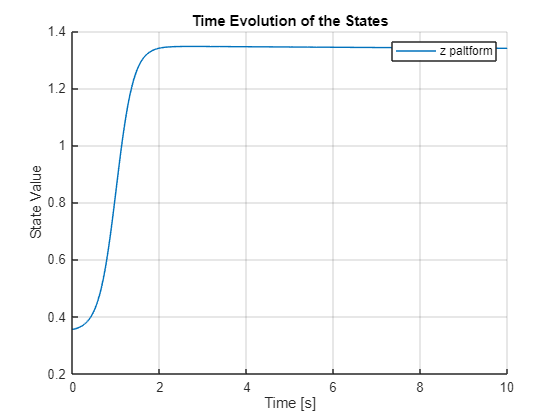

figure;
hold on;

numStates = min(1, size(state, 2));
for i = 1:numStates
    plot(simParams.tspan, state1(:, i), 'DisplayName', ['z paltform']);
end

xlabel('Time [s]');
ylabel('State Value');
legend show;
title('Time Evolution of the States');
grid on;

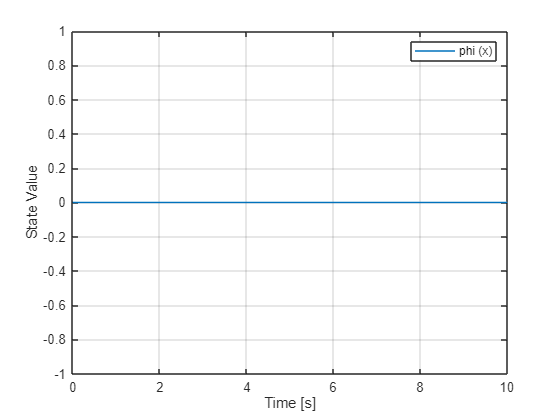


figure;

numStates = min(2, size(state, 2));  %phi
plot(simParams.tspan, state1(:, numStates), 'DisplayName', ['phi (x)']);
xlabel('Time [s]');
ylabel('State Value');
legend show;
grid on;

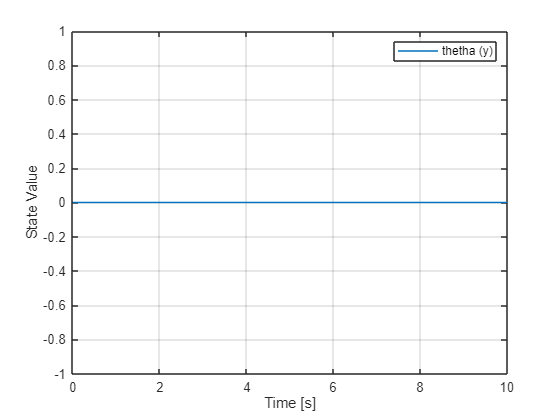


numStates = min(3, size(state, 2));  %thetha
plot(simParams.tspan, state1(:, numStates), 'DisplayName', ['thetha (y) ']);
xlabel('Time [s]');
ylabel('State Value');
legend show;
grid on;

# Simscape Model

To illustrate its dynamic response, the following video shows the platform's behavior when three sinusoidal movements are applied to the actuators.

# Conclusion

Despite its utility, the developed model has inherent limitations that distinguish it from the behavior of a real system. These limitations stem from both the physical configuration of the platform and the assumptions made during the modeling phase.

**1. Degrees of Freedom (3-DOF vs. 6-DOF)**

The most significant limitation of the system lies in its 3 degrees of freedom (heave, pitch, roll), compared to the 6-DOF of a real vehicle. The absence of lateral (sway), longitudinal (surge), and vertical axis (yaw) rotation prevents the direct reproduction of fundamental driving sensations, such as:

- Sustained acceleration or braking (related to surge).

- Lateral slip or centrifugal forces in a turn (related to sway).

- Vehicle rotation or yaw (related to yaw).

**2. Physical Constraints and Motion Cueing Algorithms**

 The platform operates within defined physical limits, which prevent it from replicating the movements of a real vehicle on a 1:1 scale. Added to this are the intrinsic limits of the actuators, whose maximum velocity (800 mm/s) and acceleration (0.8 g) are specified in the datasheet.

These physical constraints necessitate the use of motion cueing algorithms. Such algorithms are tasked with "translating" the vehicle's dynamics and accelerations into platform movements that, while remaining within the limited workspace, manage to provide the driver with a plausible sense of motion. However, this introduces two compromises:

- High-Frequency Events: The platform's ability to reproduce road vibrations or rapid impacts is limited by the maximum acceleration of the actuators.

- Command Saturation: If a simulated maneuver requires an acceleration exceeding 0.8 g, the control algorithm must "clip" or filter the command, delivering a movement that is compatible with the physical limits but loses realism for the driver.

**3. Modeling Assumptions**

The model is based on several key assumptions that, although justified to simplify the analysis, introduce discrepancies with real-world behavior:

- Small-Angle Approximation: Although verified a posteriori, this remains a simplification compared to the real, nonlinear kinematics, especially during large maneuvers.

- Platform as a Rigid Body: This assumption ignores possible structural flexibilities or deformations of the platform, which could introduce secondary dynamics.

- Friction Neglected: Is possible that the  friction (viscous in the actuators or sliding in the joints) plays a non-negligible role. The absence of friction in this model leads to an unrealistic estimation of energy consumption and long-term positioning accuracy.

Every assumption, however small, introduces a discrepancy between the model and reality. However, the choice of the level of approximation represents a fundamental engineering trade-off between model fidelity and its computational complexity. The definition of this balance is up to the modeler, in accordance with the specific goals and requirements of the project.